# Analysis of RDA output 

load("output_table.mat")
load("MergedModel_changedBounds.mat")

changeCobraSolver('glpk')

Unrecognized function or variable 'ChangeCobraSolver'.

% 'BIO0100'	Body (including storage)

dat = output_table{1}

dat = 5280×4 table
    grRatio    grRateKO    hasEffect      delRxn   
    _______    ________    _________    ___________

          1    0.069212      true       {'EX00253'}
          1    0.069212      false      {'EXC0161'}
          1    0.069212      false      {'TCE5369'}
          1    0.069212      false      {'TCE5368'}
          1    0.069212      false      {'TCE5361'}
          1    0.069212      false      {'TCE5360'}
          1    0.069212      false      {'TCE5363'}
          1    0.069212      false      {'TCE5362'}
    0.98444    0.068135      true       {'RM01360'}
          1    0.069212      false      {'TCE5364'}
          1    0.069212      false      {'TCE5367'}
          1    0.069212      false      {'TCE5366'}
          1    0.069212      false      {'EX02512'}
          1    0.069212      false      {'RC02493'}
          1 


has_effect = (dat.grRatio < 0.97 | isnan(dat.grRatio))

has_effect = 5280×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0



eff_delRxn = dat.delRxn(has_effect)

eff_delRxn = 456×1 cell array
    {'RC03660'}
    {'RC00946'}
    {'RC04311'}
    {'RC03665'}
    {'RC03664'}
    {'RCC0102'}
    {'RCC0106'}
    {'RC01121'}
    {'RC00093'}
    {'RC01321'}
    {'RCC0079'}
    {'RCC0076'}
    {'RCC0072'}
    {'RCC0073'}
    {'RCC0070'}
    {'RCC0071'}
    {'DGR0016'}
    {'DGR0014'}
    {'DGR0013'}
    {'DGR0012'}
    {'DGR0011'}
    {'RC06259'}
    {'RC06258'}
    {'DGR0019'}
    {'BIO0100'}
    {'RC02222'}
    {'RC09845'}
    {'RC09844'}
    {'TCE1301'}
    {'RC02003'}



eff_grRateKO = dat.grRateKO(has_effect)

eff_grRateKO =          0
    0.0587
    0.0000
         0
         0
    0.0000
    0.0589
    0.0000
       NaN
         0


% Look at matched iCEL reactions met <=> met[COMMON]
dataTable = readtable("dataTable_iCEL.xlsx");

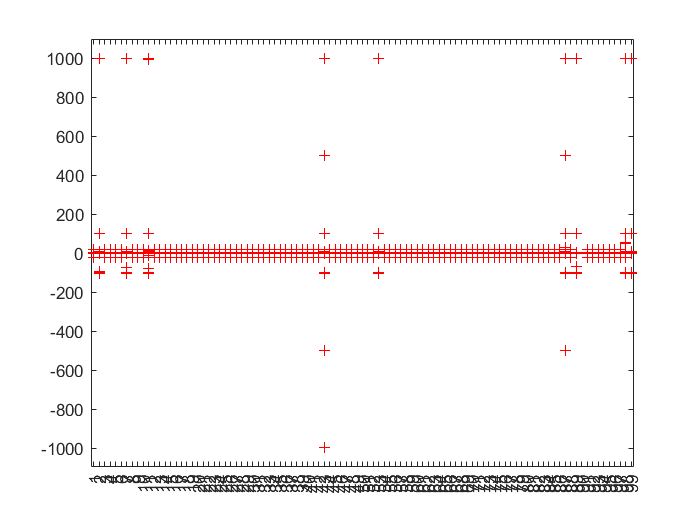




bact_EX_matched_index_iCEL = findRxnIDs(MergedModel_test, table2array(dataTable(:,"model_rxns")));

ex_Flux_iCEL = output_table{1,3}(has_effect,bact_EX_matched_index_iCEL);

ex_Flux_iCEL = array2table(ex_Flux_iCEL);

varNames = dataTable(:,"model_rxns");
varNames.model_rxns{86} = 'EX00243.2';

ex_Flux_iCEL.Properties.VariableNames = table2array(varNames);
ex_Flux_iCEL.Properties.RowNames = table2array(output_table{1,1}(has_effect,4));


boxplot(table2array(ex_Flux_iCEL), 'Colors', 'b','BoxStyle','filled')


log_FLux = log(table2array(ex_Flux_iCEL))

log_FLux =   -4.5175 + 0.0000i  -4.5463 + 0.0000i  -4.5175 + 0.0000i  -4.5175 + 0.0000i  -4.5175 + 0.0000i  -4.5175 + 0.0000i  -4.5183 + 0.0000i  -4.5175 + 0.0000i  -4.5175 + 0.0000i  -4.5175 + 0.0000i  -4.5333 + 0.0000i  -4.5175 + 0.0000i  -4.5175 + 0.0000i  -4.5175 + 0.0000i  -4.5175 + 0.0000i  -4.5175 + 0.0000i  -4.5175 + 0.0000i  -4.5175 + 0.0000i  -4.5175 + 0.0000i  -4.5175 + 0.0000i  -4.5175 + 0.0000i  -4.5175 + 0.0000i  -4.5175 + 0.0000i  -4.5175 + 0.0000i  -4.5175 + 0.0000i  -4.5175 + 0.0000i  -4.5175 + 0.0000i  -4.5175 + 0.0000i  -4.5175 + 0.0000i  -4.5175 + 0.0000i  -4.5175 + 0.0000i  -4.5175 + 0.0000i  -4.5175 + 0.0000i  -4.5175 + 0.0000i  -4.5175 + 0.0000i  -4.5175 + 0.0000i  -4.5175 + 0.0000i  -4.5175 + 0.0000i  -4.5175 + 0.0000i  -4.5175 + 0.0000i  -4.5175 + 0.0000i  -4.5175 + 0.0000i  -4.5176 + 0.0000i  -4.5175 + 0.0000i  -4.5175 + 0.0000i  -4.5175 + 0.0000i  -4.5175 + 0.0000i  -4.5175 + 0.0000i  -4.5175 + 0.0000i  -4.5175 + 0.0000i
  -5.9583 + 0.0000i  -6.1653 + 0.0000i

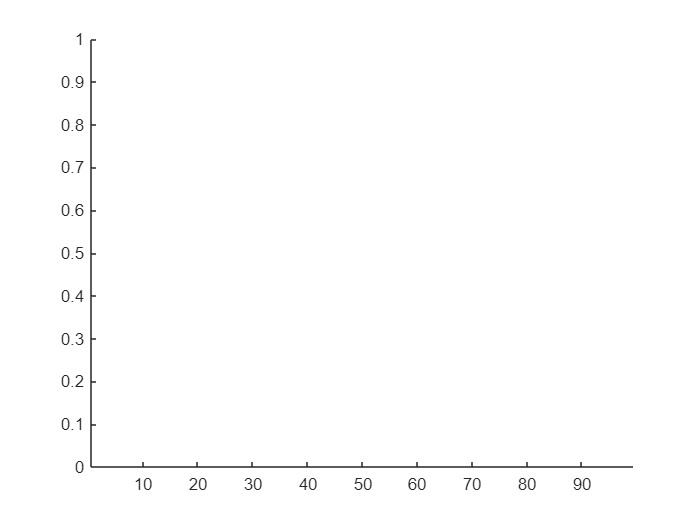

Error using matlab.graphics.axis.Axes/set
Value must be a 1x2 vector of numeric type in which the second element is greater than the first element or is Inf.

Error in axis>LocSetLimits (line 292)
    set(ax,...

Error in axis (line 113)
                LocSetLimits(ax(j),cur_arg,names);

boxplot(log(table2array(ex_Flux_iCEL)))

dataTable_myb11 = readtable("dataTable_myb11.xlsx");

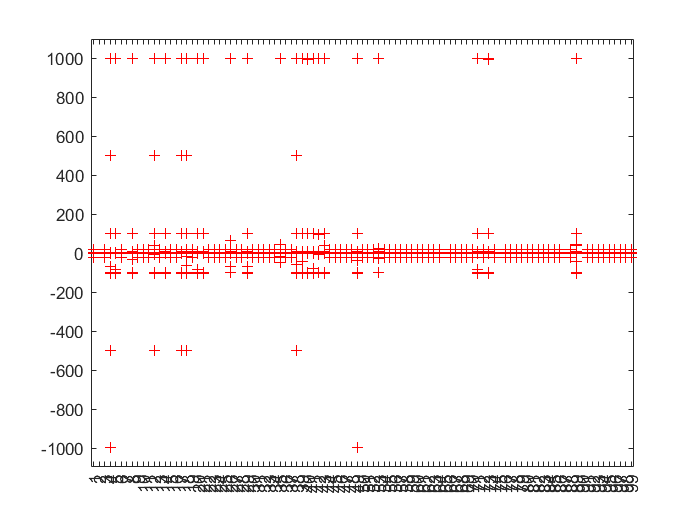



bact_EX_matched_index = findRxnIDs(MergedModel_test, table2array(dataTable_myb11(:,"model_rxns")));

ex_Flux = output_table{1,3}(has_effect,bact_EX_matched_index);

ex_Flux = array2table(ex_Flux);

varNames_myb11 = dataTable_myb11(:,"model_rxns");


ex_Flux.Properties.VariableNames = table2array(varNames_myb11);
ex_Flux.Properties.RowNames = table2array(output_table{1,1}(has_effect,4));

boxplot(table2array(ex_Flux))

% FVA


% printFluxBounds(MergedModel_FVA,{'EX_cpd11416_c0'})
% printFluxBounds(MergedModel_FVA,{'BIO0100'})
% %fluxVariability(MergedModel_test, )


x = cat(1, bact_EX_matched_index_iCEL, bact_EX_matched_index);




in_list = output_table_MYBfixed{1,1}(table2array(output_table_MYBfixed{1,1}(:,3)) == 1, "delRxn");
FVA_results = cell([1075 3]);

for i = 1:height(in_list)
    MergedModel_FVA = MergedModel_test;
    MergedModel_FVA = changeObjective(MergedModel_FVA, 'BIO0100',1);

    MergedModel_FVA = changeRxnBounds(MergedModel_FVA, 'EX_cpd11416_c0',1.644,"b");


    MergedModel_FVA = changeRxnBounds(MergedModel_FVA, table2array(in_list(i,1)),0,"b");
tic
    [minFlux, maxFlux] = fluxVariability(MergedModel_FVA,'rxnNameList', MergedModel_test.rxns(x))
toc
    FVA_results{i,1} = table2array(in_list(i,1));
    FVA_results{i,2} = num2cell(minFlux);
    FVA_results{i,3} = num2cell(maxFlux);


end

minFlux =          0
    0.0671
         0
         0
         0
         0
    0.0153
         0
         0
         0


maxFlux =     0.0000
    0.0675
    0.0000
    0.0000
    0.0000
    0.0000
    0.0154
    0.0000
    0.0000
    0.0000


Elapsed time is 64.672795 seconds.


minFlux =          0
    0.0674
         0
         0
         0
         0
    0.0153
         0
         0
         0


maxFlux =     0.0000
    0.0678
    0.0000
    0.0000
    0.0000
    0.0000
    0.0156
    0.0000
    0.0000
    0.0000


Elapsed time is 65.064394 seconds.


minFlux =          0
   -2.1858
         0
         0
         0
         0
         0
         0
         0
         0


maxFlux =     0.2319
    0.0897
    0.6344
    0.4638
    0.0351
    0.7909
    0.0231
    0.0279
    0.3955
    0.3955


Elapsed time is 60.034284 seconds.


minFlux =          0
    0.0671
         0
         0
         0
         0
    0.0152
         0
         0
         0


maxFlux =     0.0000
    0.0675
    0.0000
    0.0000
    0.0000
    0.0000
    0.0155
    0.0000
    0.0000
    0.0000


Elapsed time is 65.575772 seconds.


minFlux =          0
    0.0671
         0
         0
         0
         0
    0.0154
         0
         0
         0


maxFlux =     0.0000
    0.0674
    0.0000
    0.0000
    0.0000
    0.0000
    0.0154
    0.0000
    0.0000
    0.0000


Elapsed time is 65.184860 seconds.


minFlux =          0
    0.0671
         0
         0
         0
         0
    0.0153
         0
         0
         0


maxFlux =     0.0000
    0.0675
    0.0000
    0.0000
    0.0000
    0.0000
    0.0155
    0.0000
    0.0000
    0.0000


Elapsed time is 74.542797 seconds.


minFlux =          0
    0.0671
         0
         0
         0
         0
    0.0152
         0
         0
         0


maxFlux =     0.0000
    0.0675
    0.0000
    0.0000
    0.0000
    0.0000
    0.0154
    0.0000
    0.0000
    0.0000


Elapsed time is 62.249496 seconds.


minFlux =          0
   -0.2855
         0
         0
         0
         0
    0.0000
         0
         0
         0


maxFlux =     0.0400
    0.0708
    0.1188
    0.0803
    0.0102
    0.1728
    0.0166
    0.0128
    0.1156
    0.0963


Elapsed time is 65.546607 seconds.


minFlux =          0
    0.0671
         0
         0
         0
         0
    0.0153
         0
         0
         0


maxFlux =     0.0000
    0.0675
    0.0000
    0.0000
    0.0000
    0.0000
    0.0154
    0.0000
    0.0000
    0.0000


Elapsed time is 69.987937 seconds.


Error using fluxVariability>calcSolForEntry (line 667)
A Solution could not be found!
This should not be possible but can happenif the used solver cannot properly handle unboundedness, or if there are numerical issues.
Please try to use a different solver.


Error in fluxVariability (


for i = 1:9

scatter(1:198,100*cell2mat(FVA_results{i,2}))
hold on
end


figure
for i = 1:9

scatter(1:198,cell2mat(FVA_results{i,3}))
hold on
end